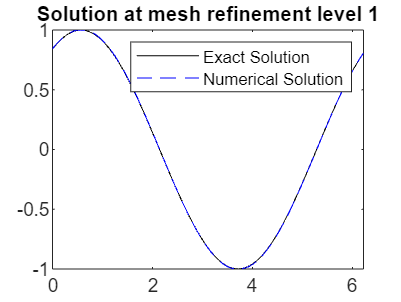

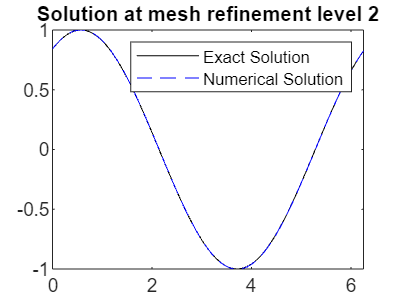

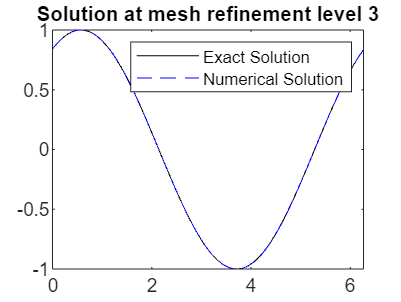

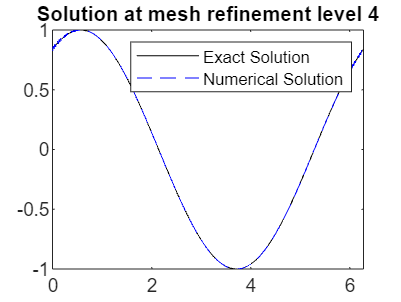

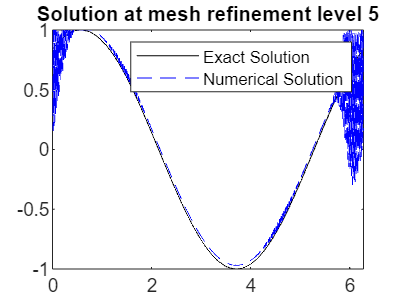

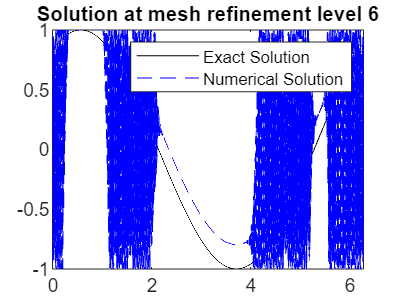

% Sanaz Hami
% 1D Linear Advection integrated with Modified DR Function with Vervose

% Initialization of parameters
xa = 0;
xb = 2 * pi;
T = 1;
m = -1; % Define lower bound
M = 1; % Define upper bound
lambda = 0.5; % Relaxation parameter for DR
epsilon = 1e-6; % Convergence criterion for DR
max_iter = 1000; % Maximum iterations for DR
verbose = false; % Set to true for detailed output
v0 = @(x) sin(x); % Initial condition function
errtab = zeros(6, 2); % Error table initialization

% Main loop for mesh refinement
for kk = 1:6
    Nx = 100 * (2 ^ (kk - 1)) - 1; % Mesh size calculation
    h = (xb - xa) / (Nx + 1); % Spatial step size
    k = .1*h; 
    v = zeros(1, Nx + 3); % Initialization of solution vector
    x = linspace(xa, xb - h, Nx + 1); % Spatial grid
    v(2:Nx + 2) = v0(x); % Set initial condition

    % Time marching
    for ii = 1:floor(T / k)
        v_new = zeros(size(v)); % Initialize new solution vector
        for jj = 2:Nx + 2
            v_new(jj) = v(jj) + ((k / h) / 2) * (v(jj + 1) - v(jj - 1));
        end
        % Periodic boundary conditions
        v_new(1) = v_new(Nx + 2);
        v_new(Nx + 3) = v_new(2);
        v = v_new;

        % Post-process using modified DR function
        u_guess = v(2:Nx+2);
        v(2:Nx+2) = DR_modified(v(2:Nx+2), m, M, u_guess, epsilon, max_iter, lambda, verbose);
    end

    % Calculate error and plot
    u_exac = v0(x + T);
    errtab(kk, 1) = sqrt(sum((u_exac - v(2:Nx + 2)).^2 * h));
    figure;
    plot(x, u_exac, 'k-', x, v(2:Nx + 2), 'b--');
    legend('Exact Solution', 'Numerical Solution');
    title(['Solution at mesh refinement level ', num2str(kk)]);
end


% Compute the order of accuracy
for kk = 2:5
    if errtab(kk - 1, 1) > 0
        errtab(kk, 2) = log(errtab(kk - 1, 1) / errtab(kk, 1)) / log(2);
    else
        errtab(kk, 2) = NaN; % Assign NaN if the previous error is zero
    end
end

% Display the error table with the order of accuracy
disp('Error table with the order of accuracy:');

Error table with the order of accuracy:


format shortE
disp(errtab);

   6.1930e-03            0
   3.4772e-03   8.3270e-01
   2.5282e-03   4.5982e-01
   7.8885e-03  -1.6416e+00
   3.6455e-01  -5.5302e+00
   1.6829e+00            0




% Definition of the modified DR function

function [u_mod] = DR_modified(u_bar, m, M, u_guess, epsilon, max_iter, lambda, verbose)
    % Initialization
    N = length(u_bar); % Number of elements in u_bar
    b = sum(u_bar); % Sum of u_bar, which should be preserved
    u_mod = u_guess; % Initial guess for the solution

    % DR iteration based on algorithm
    for iter = 1:max_iter
        % Step I: Projection onto the set [m, M]
        y = min(max(u_mod, m), M); 

        % Step II: Reflection step
        y_reflected = 2 * y - u_mod;

        % Step III: Projection onto the hyperplane defined by the conservation constraint
        y_next = y_reflected - (sum(y_reflected) - b) / N;

        % Relaxation step
        u_mod = u_mod + lambda * (y_next - u_mod);

        % Check for convergence
        if norm(u_mod - u_guess, 2) <= epsilon
            if verbose
                disp(['Converged in ', num2str(iter), ' iterations.']);
            end
            break;
        end
    end

    if iter == max_iter && verbose
        disp('Maximum iterations reached without convergence.');
    end
end

